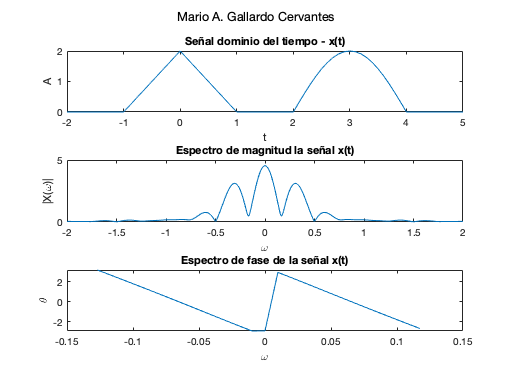

clc
close all
clear all

df=0.01;
fs=10;
ts=1/fs;
t=[-5:ts:5];
x1=zeros(size(t));
x1(41:51)=t(41:51)+1;
x1(52:61)=-t(52:61)+1;
x1(71:81)=-sin((pi/2).*t(71:81));
x1(82:91)=-sin((pi/2).*t(82:91));
x1=2*x1;
figure
subplot(3,1,1)
plot(t,x1)
xlim([-2 5])
title("Señal dominio del tiempo - x(t)")
xlabel("t")
ylabel("A")

[X1,x11,df1]=Fftseq(x1,ts,df);
X11=X1/fs;
f=[0:df1:df1*(length(x11)-1)]-fs/2;
subplot(3,1,2)
plot(f,fftshift(abs(X11)))
xlim([-2 2])
title("Espectro de magnitud la señal x(t)")
xlabel("\omega")
ylabel("|X(\omega)|")
subplot(3,1,3)
plot(f(500:525),fftshift(angle(X11(500:525))))
title("Espectro de fase de la señal x(t)")
xlabel("\omega")
ylabel("\theta")

sgtitle("Mario A. Gallardo Cervantes")

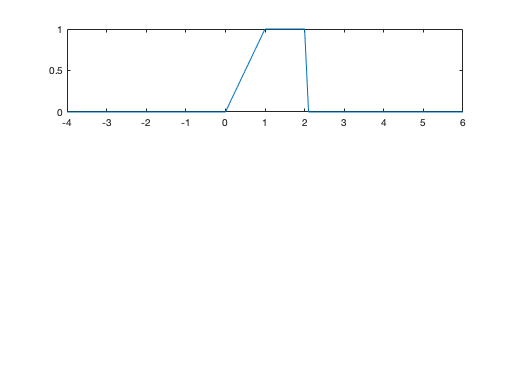

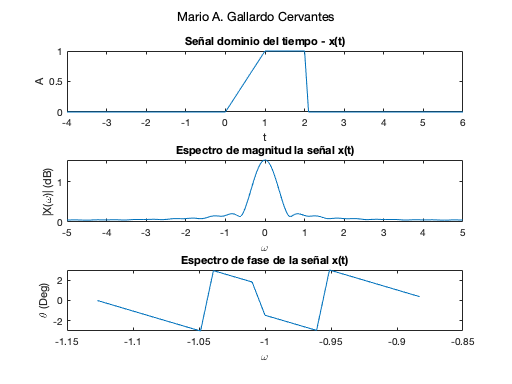

%parte B
